SIZES = [10,20,30,40,50,60,70,80,90,100,150,200,250,300,350,400];
iters = 100;

%% initialized exp_data %%
init_SNR_iters = [];
rnd_SNR_iters = [];
exp_data.iterations = [];
exp_data.type = [];
exp_data.SNR = ones(1,iters)*SIZES(1);
for i=2:size(SIZES)
    exp_data.SNR = [exp_data.SNR, ones(1,iters)*SIZES(i)];
end

% exp_data.SNR = [exp_data.SNR, ones(1,iters)*SIZES(2)];
% exp_data.SNR = [exp_data.SNR, ones(1,iters)*SIZES(3)];
% exp_data.SNR = [exp_data.SNR, ones(1,iters)*SIZES(4)];
% exp_data.SNR = [exp_data.SNR, ones(1,iters)*SIZES(5)];
% exp_data.SNR = [exp_data.SNR, ones(1,iters)*SIZES(6)];
% exp_data.SNR = [exp_data.SNR, ones(1,iters)*SIZES(7)];
% exp_data.SNR = [exp_data.SNR, ones(1,iters)*SIZES(8)];
%% -----------------   %%
for SIZE=1:size(SIZES,2)
    for iter=1:iters
        dim = [SIZES(SIZE),SIZES(SIZE),SIZES(SIZE)];
        T = zeros(dim);
        for i = 1:size(T,1)
            T(i,:,:) = diag(randn(size(T,2),1));
        end
        x = randn(dim(2),1);
    
        b = tmprod(T,{x.',x.'},[2,3]);

        tic;
        xest = solve_part_diag(T,b);
        exp_data.iterations = [exp_data.iterations,toc];
    
    end
end

% boxchart(categorical(exp_data.SNR),exp_data.iterations)
clf
n3 = [];
for i=1:size(SIZES,2)
    n3 = [n3,SIZES(i)^3]
end

n3 = 1000

n3 =         1000        8000


n3 =         1000        8000       27000


n3 =         1000        8000       27000       64000


n3 =         1000        8000       27000       64000      125000


n3 =         1000        8000       27000       64000      125000      216000


n3 =         1000        8000       27000       64000      125000      216000      343000


n3 =         1000        8000       27000       64000      125000      216000      343000      512000


n3 =         1000        8000       27000       64000      125000      216000      343000      512000      729000


n3 =         1000        8000       27000       64000      125000      216000      343000      512000      729000     1000000


n3 =         1000        8000       27000       64000      125000      216000      343000      512000      729000     1000000     3375000


n3 =         1000        8000       27000       64000      125000      216000      343000      512000      729000     1000000     3375000     8000000


n3 =         1000        8000       27000       64000      125000      216000      343000      512000      729000     1000000     3375000     8000000    15625000


n3 =         1000        8000       27000       64000      125000      216000      343000      512000      729000     1000000     3375000     8000000    15625000    27000000


n3 =         1000        8000       27000       64000      125000      216000      343000      512000      729000     1000000     3375000     8000000    15625000    27000000    42875000


n3 =         1000        8000       27000       64000      125000      216000      343000      512000      729000     1000000     3375000     8000000    15625000    27000000    42875000    64000000


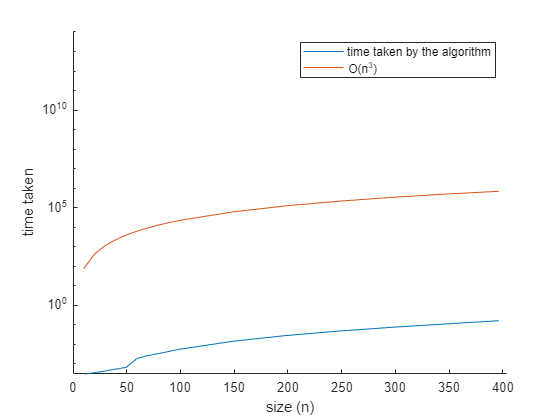

hold on 
plot(SIZES,medtime)
plot(SIZES,n3)
hold off
ylabel('time taken')
xlabel('size (n)')
%title('Iterations required for optimization function(noise on the coeffiecient tensor,\{2,3\} diag and right hand side b)')
legend('time taken by the algorithm','O(n^3)')
% legend
ylim([0,100000000000])
set(gca, 'YScale', 'log')

exp_data.SNR = ones(1,iters)*SIZES(1);
SIZES

SIZES =     10    20    30    40    50    60    70    80    90   100   110   120


for i=2:size(SIZES,2)
    exp_data.SNR = [exp_data.SNR, ones(1,iters)*SIZES(i)];
end
size(exp_data.SNR)

ans =            1        1200


exp_data_dupe = exp_data;
exp_data_dupe.iterations = exp_data_dupe.iterations';
exp_data_dupe.SNR = exp_data.SNR';
 exp_data_dupe= rmfield(exp_data_dupe,'type')

exp_data_dupe = struct with fields:
    iterations: [1200×1 double]
           SNR: [1200×1 double]


exp_table = struct2table(exp_data_dupe)

exp_table = 1200×2 table
    iterations    SNR
    __________    ___

     0.017003     10 
    0.0060892     10 
    0.0050287     10 
    0.0034256     10 
    0.0071502     10 
    0.0040711     10 
    0.0030638     10 
    0.0026623     10 
    0.0038273     10 
    0.0030965     10 
    0.0022791     10 
    0.0023783     10 
    0.0023776     10 
    0.0033566     10 
     0.003347     10 
    0.0026596     10 


medtime = groupsummary(exp_table.iterations,categorical(exp_table.SNR),'median');

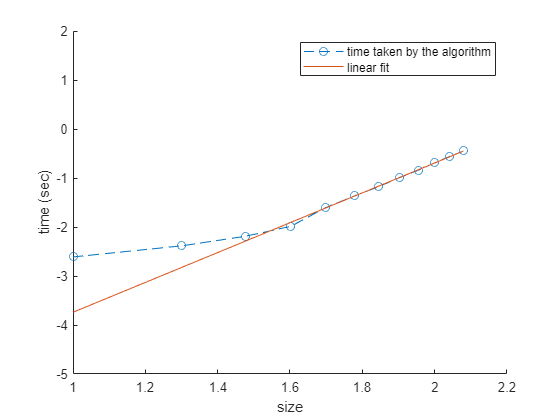

% boxchart(categorical(exp_data.SNR),exp_data.iterations)
clf
n3 = SIZES.^3;
hold on 
plot(log10(SIZES),log10(medtime),'--O')
plot(log10(SIZES),fitpoints)
hold off
ylabel('time (sec)')
xlabel('size')
%title('Iterations required for optimization function(noise on the coeffiecient tensor,\{2,3\} diag and right hand side b)')
legend('time taken by the algorithm','linear fit')
% legend
ylim([-5,2])

% xlim([-2.2,2.2])
% set(gca, 'YScale', 'log')

p1(1)

ans = 3.0466

p1 = polyfit(log10(SIZES(5:end)),log10(medtime(5:end)),1); 
fitpoints=p1(1)*log10(SIZES) + p1(2);

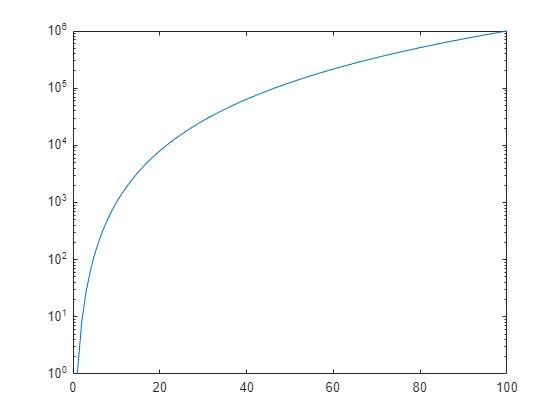

xvals = (1:100);
op = xvals.^3;
semilogy(xvals,op)

SIZES = [10,20,30,40,50,60,70,80,90,100,110,120];
iters = 100;

%% initialized exp_data %%
init_SNR_iters = [];
rnd_SNR_iters = [];
exp_data.iterations = [];
exp_data.type = [];
exp_data.SNR = ones(1,iters)*SIZES(1);
for i=2:size(SIZES)
    exp_data.SNR = [exp_data.SNR, ones(1,iters)*SIZES(i)];
end

% exp_data.SNR = [exp_data.SNR, ones(1,iters)*SIZES(2)];
% exp_data.SNR = [exp_data.SNR, ones(1,iters)*SIZES(3)];
% exp_data.SNR = [exp_data.SNR, ones(1,iters)*SIZES(4)];
% exp_data.SNR = [exp_data.SNR, ones(1,iters)*SIZES(5)];
% exp_data.SNR = [exp_data.SNR, ones(1,iters)*SIZES(6)];
% exp_data.SNR = [exp_data.SNR, ones(1,iters)*SIZES(7)];
% exp_data.SNR = [exp_data.SNR, ones(1,iters)*SIZES(8)];
options = struct;
options.TolFun = eps^2;
options.TolX = eps;
options.LargeScale = false;
%% -----------------   %%
for SIZE=1:size(SIZES,2)
    for iter=1:iters
        dim = [SIZES(SIZE),SIZES(SIZE),SIZES(SIZE)];
        T = zeros(dim);
        for i = 1:size(T,1)
            T(i,:,:) = circulant(randn(dim(2),1));
        end
        x = randn(dim(2),1);
    
        b = tmprod(T,{x.',x.'},[2,3]);

        tic;
        xest = solve_circ(T,b);
        exp_data.iterations = [exp_data.iterations,toc];
    
    end
end

SIZES = [10,20,30,40,50,60,70,80,90,100,110,120];
iters = 100;

%% initialized exp_data %%
init_SNR_iters = [];
rnd_SNR_iters = [];
exp_data.iterations = [];
exp_data.type = [];
exp_data.SNR = ones(1,iters)*SIZES(1);
for i=2:size(SIZES)
    exp_data.SNR = [exp_data.SNR, ones(1,iters)*SIZES(i)];
end

% exp_data.SNR = [exp_data.SNR, ones(1,iters)*SIZES(2)];
% exp_data.SNR = [exp_data.SNR, ones(1,iters)*SIZES(3)];
% exp_data.SNR = [exp_data.SNR, ones(1,iters)*SIZES(4)];
% exp_data.SNR = [exp_data.SNR, ones(1,iters)*SIZES(5)];
% exp_data.SNR = [exp_data.SNR, ones(1,iters)*SIZES(6)];
% exp_data.SNR = [exp_data.SNR, ones(1,iters)*SIZES(7)];
% exp_data.SNR = [exp_data.SNR, ones(1,iters)*SIZES(8)];
options = struct;
options.TolFun = eps^2;
options.TolX = eps;
options.LargeScale = false;
%% -----------------   %%
for SIZE=1:size(SIZES,2)
    for iter=1:iters
        dim = [SIZES(SIZE),SIZES(SIZE),SIZES(SIZE)];
        T = zeros(dim);
        for i = 1:size(T,1)
            T(i,:,:) = circulant(randn(dim(2),1),-1);
        end
        x = randn(dim(2),1);
    
        b = tmprod(T,{x.',x.'},[2,3]);

        tic;
        xest = solve_hankel(T,b);
        exp_data.iterations = [exp_data.iterations,toc];
    
    end
end